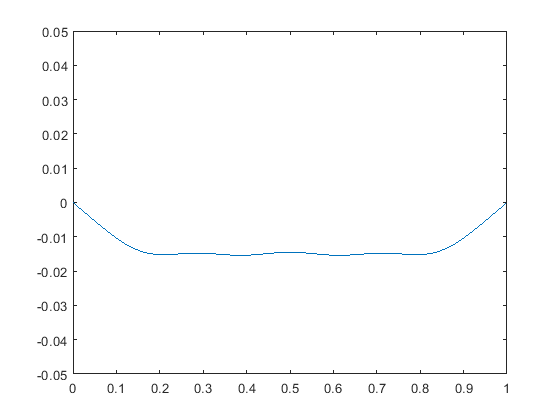

clearvars;clc;
AD=[0.0405 0 -0.0045 0 0.0016 0 0.0008 0 0.0005 0]; 
%optei por escrever o vetor AD
nn=1000;
xx= linspace(0,1,nn);
numlamb=10;
L=1;
c=6.325;
    for t=0:0.01:2
        u=0;
        for k=1:numlamb
        u= u + AD(k)*sin(k*pi*xx).*cos(k*pi/L*c*t);
        end
        plot(xx,u)
        ylim([-0.05 0.05])
        drawnow
    end